clear



rng(1); % for reproducibility

% Class 1: Inner Circle (e.g., center cluster)
N1 = 50;
R1 = 0.5;
T1 = 2*pi*rand(N1, 1);
X1 = [R1*rand(N1, 1).*cos(T1), R1*rand(N1, 1).*sin(T1)];
Y1 = repmat({'Class1'}, N1, 1);

% Class 2: Middle Ring (e.g., a surrounding ring)
N2 = 50;
R_min2 = 1.0;
R_max2 = 1.5;
T2 = 2*pi*rand(N2, 1);
R_rand2 = (R_max2 - R_min2) * rand(N2, 1) + R_min2;
X2 = [R_rand2.*cos(T2), R_rand2.*sin(T2)];
Y2 = repmat({'Class2'}, N2, 1);

% Class 3: Outer Ring (e.g., another surrounding ring)
N3 = 50;
R_min3 = 2.0;
R_max3 = 2.5;
T3 = 2*pi*rand(N3, 1);
R_rand3 = (R_max3 - R_min3) * rand(N3, 1) + R_min3;
X3 = [R_rand3.*cos(T3), R_rand3.*sin(T3)];
Y3 = repmat({'Class3'}, N3, 1);

% Combine the data
X = [X1; X2; X3];
Y = string([Y1; Y2; Y3]);

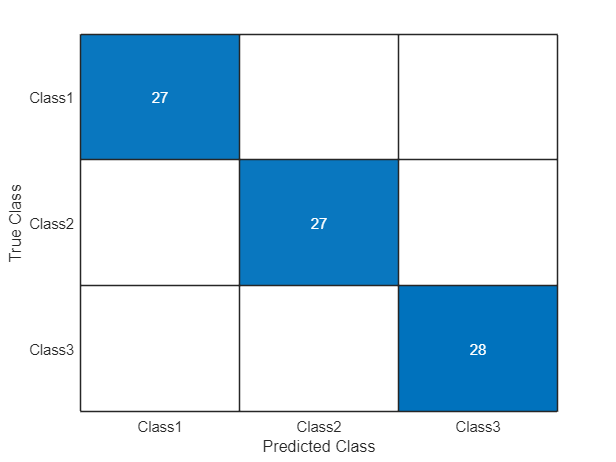

fileDirectory = fullfile('D:/Proton Drive/Lasseb200/My files/Master/MachineLearning/KernelSVM');
addpath(fileDirectory);
cv = cvpartition(Y,'Holdout',0.55);
X_training = X(cv.training,:); Y_training = Y(cv.training);
X_test = X(cv.test,:);
Y_pred = kernelSVM(X_training,Y_training,X_test,'poly',1,{2,1});
Y_test = Y(cv.test);
confusionchart(Y_test, Y_pred);